# Acoustic Image Exampleclait.

## Setup scene and sensor

structScene = struct();
structScene.targetAzimuth = [0  -45  45  20  -20  70];
structScene.targetElevation = [0  0    0   0   0    0];
structScene.targetRange    = [2  1.5  1.8 2.5 2.5  3.0];
structScene.targetStrength = [1  1    1   1   1    1  ];
structScene.speedOfSound = 343;

structSensor = struct();
structSensor.sampleRate = 450e3;
structSensor.emissionSignal = clait.fm_sweep(80e3, 20e3, structSensor.sampleRate, 2, 1, 10);
structSensor.coordinatesEmitter = [0 0 0.05];
structSensor.numSamplesSensor = 15000;
structSensor.coordinatesMicrophones = [0 -0.0384 0.0151; 0 -0.0232 0.0101; 0 -0.0121 0.0164; 0 -0.0046 0.0153; ...
                                       0 -0.0367 0.0054; 0 -0.0144 0.0061; 0 0.0054 0.0011; 0 0.0273 -0.0027; ...
                                       0 -0.0387 0.0001; 0 -0.0281 0.0002; 0 -0.0094 -0.0013; 0 -0.0060 -0.0000; ...
                                       0 -0.0357 -0.0117; 0 -0.0318 -0.0112; 0 -0.0286 -0.0166; 0 0.0029 -0.0086; ...
                                       0 -0.0011 0.0178; 0 0.0067 0.0115; 0 0.0103 0.0144; 0 0.0172 0.0140; ...
                                       0 0.0384 0.0022; 0 0.0283 0.0162; 0 0.0354 0.0125; 0 0.0373 0.0150; ...
                                       0 -0.0084 -0.0047; 0 0.0107 -0.0111; 0 0.0189 -0.0166; 0 0.0363 -0.0101; ...
                                       0 0.0057 -0.0224; 0 -0.0036 -0.0223; 0 0.0315 -0.0161; 0 0.0083 -0.0178];
    

## Setup Imaging

structImage = struct();
structImage.directionsAzimuth = -90:2:90;
structImage.directionsElevation = zeros(size(structImage.directionsAzimuth));
structImage.numDirections = length(structImage.directionsAzimuth);
structImage.lowpassFreq = 5e3;
structImage.doEnvelope = 1;
structImage.doThresholdAtZero = 1;
structImage.decimationFactor = 10;
structImage.matchedFilterMethod = 'Normal';
structImage.matchedFilterFreq = [20e3 80e3];
structImage.doMatchedFilter = 1;
    

## Generate microphone data

dataMicrophones = clait.clait.simulateMicrophoneData(structScene, structSensor);
dataMicrophones = dataMicrophones + 0.1 * randn(size(dataMicrophones));

## Run only DAS

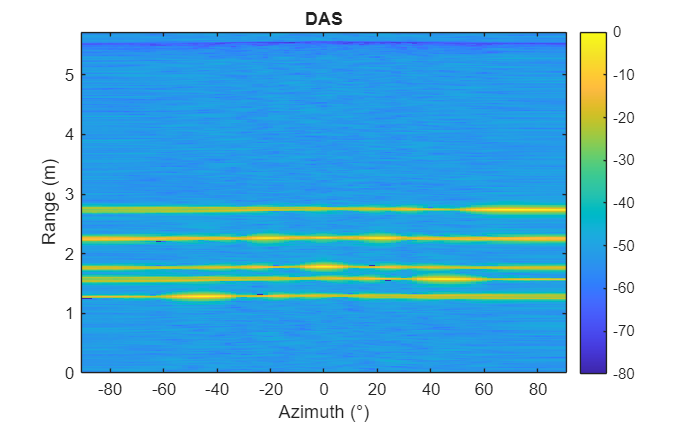

structImageDAS = structImage;
structImageDAS.methodImaging = 'DAS';
structImageDAS.coherenceType = 'none';
structImageDAS.methodProcessing = 'mexcuda'; 
imageDAS = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDAS);

maxRange = structSensor.numSamplesSensor / structSensor.sampleRate * 343 / 2;    
rangeVector = linspace( 0, maxRange, size( imageDAS, 1 ) );

dbCut = -80;
imageDASLog = clait.normLog( imageDAS, dbCut );

figure(); 
imagesc( structImage.directionsAzimuth, rangeVector, imageDASLog )
xlabel( 'Azimuth (°)' )
ylabel( 'Range (m)')
set( gca, 'ydir', 'normal' )
title( 'DAS' )
colorbar
caxis( [ dbCut 0 ] )  

## Run full image calculation

processingMethod = 'mexcuda'; 

tic
% --- DAS ---
structImageDAS = structImage;
structImageDAS.methodImaging = 'DAS';
structImageDAS.coherenceType = 'none';
structImageDAS.methodProcessing = processingMethod; 
imageDAS = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDAS);

% --- DAS-CF ---
structImageDASCF = structImage;
structImageDASCF.methodImaging = 'DAS';
structImageDASCF.coherenceType = 'CF';
structImageDASCF.methodProcessing = processingMethod; 
imageDASCF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDASCF);

% --- DMAS ---
structImageDMAS = structImage;
structImageDMAS.methodImaging = 'DMAS';
structImageDMAS.coherenceType = 'none';
structImageDMAS.methodProcessing = processingMethod; 
imageDMAS = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS);

% --- DMAS-CF ---
structImageDMASCF = structImage;
structImageDMASCF.methodImaging = 'DMAS';
structImageDMASCF.coherenceType = 'CF';
structImageDMASCF.methodProcessing = processingMethod;
imageDMASCF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMASCF);

% --- DMAS3 ---
structImageDMAS3 = structImage;
structImageDMAS3.methodImaging = 'DMAS3';
structImageDMAS3.coherenceType = 'none';
structImageDMAS3.methodProcessing = processingMethod; 
imageDMAS3 = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS3);

% --- DMAS3-CF  ---
structImageDMAS3CF = structImage;
structImageDMAS3CF.methodImaging = 'DMAS3';
structImageDMAS3CF.coherenceType = 'CF';
structImageDMAS3CF.methodProcessing = processingMethod; 
imageDMAS3CF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS3CF);

% --- DMAS4 ---
structImageDMAS4 = structImage;
structImageDMAS4.methodImaging = 'DMAS4';
structImageDMAS4.coherenceType = 'none';
structImageDMAS4.methodProcessing = processingMethod;
imageDMAS4 = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS4);

% --- DMAS4-CF  ---
structImageDMAS4CF = structImage;
structImageDMAS4CF.methodImaging = 'DMAS4';
structImageDMAS4CF.coherenceType = 'CF';
structImageDMAS4CF.methodProcessing = processingMethod; 
imageDMAS4CF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS4CF);

% --- DMAS5 ---
structImageDMAS5 = structImage;
structImageDMAS5.methodImaging = 'DMAS5';
structImageDMAS5.coherenceType = 'none';
structImageDMAS5.methodProcessing = processingMethod; 
imageDMAS5 = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS5);

% --- DMAS5-CF ---
structImageDMAS5CF = structImage;
structImageDMAS5CF.methodImaging = 'DMAS5';
structImageDMAS5CF.coherenceType = 'CF';
structImageDMAS5CF.methodProcessing = processingMethod;
imageDMAS5CF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS5CF);
toc

Elapsed time is 0.263269 seconds.


## Plot results

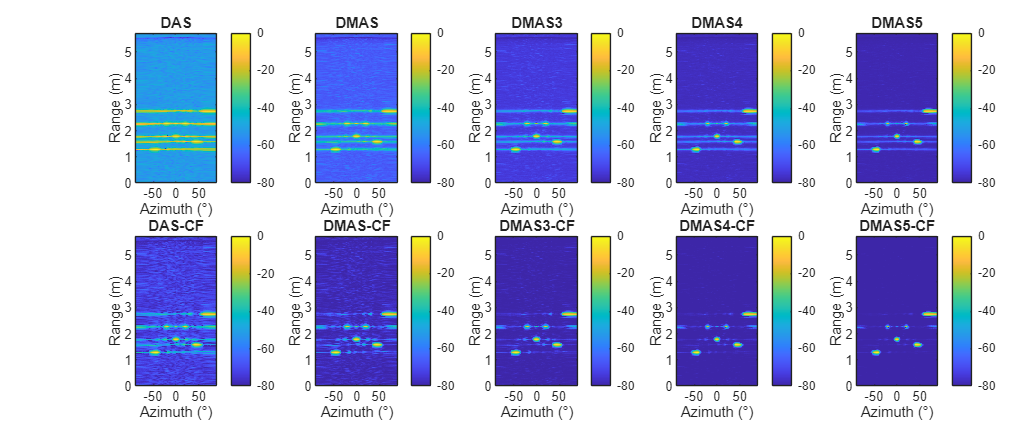

maxRange = structSensor.numSamplesSensor / structSensor.sampleRate * 343 / 2;    
rangeVector = linspace( 0, maxRange, size( imageDAS, 1 ) );    

dbCut = -80;
imageDASLog = clait.normLog( imageDAS, dbCut );
imageDASCFLog = clait.normLog( imageDASCF, dbCut );
imageDMASLog = clait.normLog( imageDMAS, dbCut );
imageDMASCFLog = clait.normLog( imageDMASCF, dbCut );
imageDMAS3Log = clait.normLog( imageDMAS3, dbCut );
imageDMAS3CFLog = clait.normLog( imageDMAS3CF, dbCut );
imageDMAS4Log = clait.normLog( imageDMAS4, dbCut );
imageDMAS4CFLog = clait.normLog( imageDMAS4CF, dbCut );
imageDMAS5Log = clait.normLog( imageDMAS5, dbCut );
imageDMAS5CFLog = clait.normLog( imageDMAS5CF, dbCut );

figure(); 
set(gcf, 'units','normalized','outerposition',[0 0 0.75 0.75]);
    tiledlayout( 2,5,'TileSpacing','tight','TileIndexing','columnmajor' )
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDASLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DAS' )
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDASCFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DAS-CF' )   
        colorbar
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMASLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS' )    
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMASCFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS-CF' ) 
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS3Log )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS3' )  
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS3CFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS3-CF' )  
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS4Log )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS4' )   
        colorbar
        caxis( [ dbCut 0 ] )
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS4CFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS4-CF' )  
        colorbar
        caxis( [ dbCut 0 ] )
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS5Log )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS5' )   
        colorbar
        caxis( [ dbCut 0 ] )
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS5CFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS5-CF' )  
        colorbar
        caxis( [ dbCut 0 ] )